# Return Theoretical BER Data for AWGN Channels

Return theoretical bit error rate data for several modulation schemes in an AWGN channel.

Create a vector of $E_{\mathrm{b}} /N_0$ values and specify the modulation order.

EbNo = (0:12)';
EbNoNew = (0:0.1:12)';
M = 8; % Modulation order
size(EbNo)

ans =     13     1


size(EbNoNew)

ans =    121     1


Return theoretical BER data for QPSK modulation.

[ber8psk1,ser8psk1] = berawgn(EbNoNew,'psk',8,'nondiff');
[ber8psk,ser8psk] = berawgn(EbNo,'psk',8,'nondiff');
[ber16qam,ser16qam] = berawgn(EbNo,'qam',16);
[ber64qam,ser64qam] = berawgn(EbNo,'qam',64);

Plot the results.

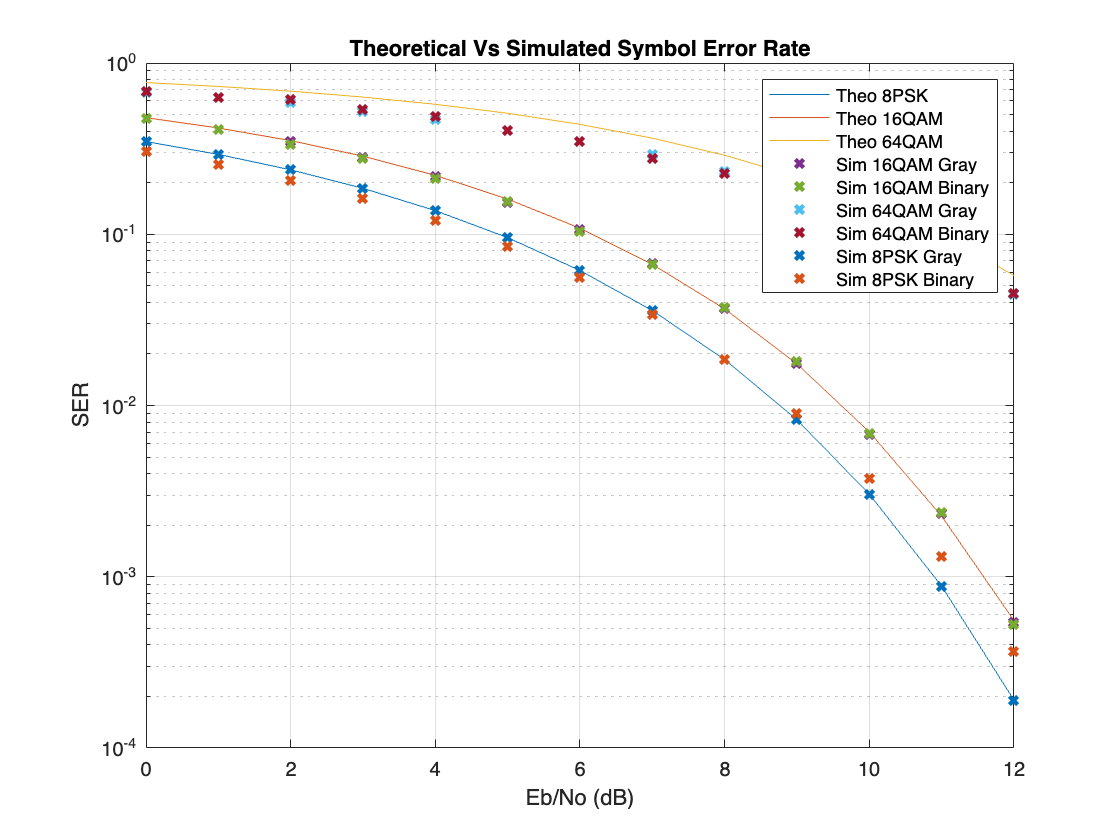

semilogy(EbNo,ser8psk,'DisplayName', 'Theo 8PSK')
hold on
semilogy(EbNo,ser16qam,'DisplayName', 'Theo 16QAM')
hold on
semilogy(EbNo,ser64qam,'DisplayName', 'Theo 64QAM')
hold on

ser_List_8PSK_Gray = zeros(size(EbNo));
for i = 1:length(EbNo)
   
    ser_List_8PSK_Gray(i) = ser8psk(i);
   
end

ser_List_8PSK_Binary = zeros(size(EbNo));
for i = 1:length(EbNo)
   
    ser_List_8PSK_Binary(i) = ser8psk1(9*i);
   
end

%semilogy(EbNo, ser_8psk_gray, 'x', 'LineWidth', 2,'DisplayName', 'Sim 8PSK Gray');
%hold on
%semilogy(EbNo, ser_8psk_binary, 'x', 'LineWidth', 2,'DisplayName', 'Sim 8PSK Binary');
%hold on
semilogy(EbNo, ser_16qam_gray, 'x', 'LineWidth', 2,'DisplayName', 'Sim 16QAM Gray');
hold on
semilogy(EbNo, ser_16qam_binary, 'x', 'LineWidth', 2,'DisplayName', 'Sim 16QAM Binary');
hold on
semilogy(EbNo, ser_64qam_gray, 'x', 'LineWidth', 2,'DisplayName', 'Sim 64QAM Gray');
hold on
semilogy(EbNo, ser_64qam_binary, 'x', 'LineWidth', 2,'DisplayName', 'Sim 64QAM Binary');
hold on
semilogy(EbNo, ser_List_8PSK_Gray, 'x', 'LineWidth', 2,'DisplayName', 'Sim 8PSK Gray');
hold on
semilogy(EbNo, ser_List_8PSK_Binary, 'x', 'LineWidth', 2,'DisplayName', 'Sim 8PSK Binary');

grid
xlabel('Eb/No (dB)')
ylabel('SER')
legend;
title("Theoretical Vs Simulated Symbol Error Rate")

*Copyright 2015 The MathWorks, Inc.*